# Channel Matched Filter Precoder

% Downlink
% Achievable Rate V.S. Correlation Parameter
% Linear Formation and Rectangular Formation


## Global Parameters

clc
clearvars


% Antennas
M1 = 8;
M2 = 8;
M = M1 * M2;

% Users
K = 10;

% Channel Length
taps = 4;
freq = 4;

% Block Length
time = 100;
cyclic_prefix = 20;

% Monte-Carlo Parameter
use = 5;

% Time Shield
shield = taps + 1;

% Normalized Distance
dn = 0.5;

% Range of Power
r = 10;
e = 10 * log10(r);

% Correlation Parameters
alpha = [0.0, 0.4, 0.7, 0.9, 0.99];
eta = [0, 50, 100, 200, 500];
mu = [0.0, pi / 6, pi / 4, pi / 3, pi / 2];

sample = 5;


## Correlation Matrix

% Linear
for i = 1 : M
    for j = 1 : M
        dist(i, j) = abs(i - j) * dn;
    end
end

fix_eta = 50;
fix_mu = 0;

for index = 1 : sample
    corr_exp_1d(:, :, index) = alpha(index) .^ dist;
    arg = fix_eta ^ 2 - 4 * (pi ^ 2) .* (dist) .^ 2 + 4i * pi * fix_eta * sin(mu(index)) .* dist;
    arg = sqrt(arg);
    corr_bsl_1d_mu(:, :, index) = besseli(0, arg) ./ besseli(0, fix_eta);
    arg = eta(index) ^ 2 - 4 * (pi ^ 2) .* (dist) .^ 2 + 4i * pi * eta(index) * sin(fix_mu) .* dist;
    arg = sqrt(arg);
    corr_bsl_1d_eta(:, :, index) = besseli(0, arg) ./ besseli(0, eta(index));
end
clear dist;

% Rectangular
i = 1;
for c1 = 1 : M1
    for r1 = 1 : M2
        j = 1;
        for c2 = 1 : M1
            for r2 = 1 : M2
                dist(i, j) = (c2 - c1) ^ 2 + (r1 - r2) ^ 2;
                j = j + 1;
            end
        end
        i = i + 1;
    end
end

for index = 1 : sample
    dist = sqrt(dist .* dn);
    corr_exp_2d(:, :, index) = alpha(index) .^ dist;
    arg = fix_eta ^ 2 - 4 * (pi ^ 2) .* (dist) .^ 2 + 4i * pi * fix_eta * sin(mu(index)) .* dist;
    arg = sqrt(arg);
    corr_bsl_2d_mu(:, :, index) = besseli(0, arg) ./ besseli(0, fix_eta);
    arg = eta(index) ^ 2 - 4 * (pi ^ 2) .* (dist) .^ 2 + 4i * pi * eta(index) * sin(fix_mu) .* dist;
    arg = sqrt(arg);
    corr_bsl_2d_eta(:, :, index) = besseli(0, arg) ./ besseli(0, eta(index));
end
clear dist;


## Channel Power Delay Profile

phase = (0 : K - 1) / 5;
for l = 1 : taps
    for k = 1 : K
        d1 = exp(-1 * phase(k) * (0 : taps - 1));
        d(l, k) = exp(-1 * phase(k) * (l - 1)) / (sum(d1));
    end
    D1 = diag(d(l, :));
    D(:, :, l) = D1;
end


## Search Tree

for index = 1 : sample
    
    exp_1D = corr_exp_1d(:, :, index);
    bsl_1D_mu = corr_bsl_1d_mu(:, :, index);
    bsl_1D_eta = corr_bsl_1d_eta(:, :, index);
    exp_2D = corr_exp_2d(:, :, index);
    bsl_2D_mu = corr_bsl_2d_mu(:, :, index);
    bsl_2D_eta = corr_bsl_2d_eta(:, :, index);

    %{
    for n = 1 : use
        
        S(:, :, n) = (sqrt(0.5)) * (randn(K, time) + 1i * randn(K, time));
    
        for l = 1 : taps
            D1 = D(:, :, l) .^ (0.5);
            H1 = (sqrt(0.5)) * (randn(M, K) + 1i * randn(M, K));
            
            Hl_exp_1D(:, :, l, n) = conj((exp_1D ^ (0.5)) * H1) * D1;
            Hl_bsl_1D(:, :, l, n) = conj((bsl_1D ^ (0.5)) * H1) * D1;
            Hl_exp_2D(:, :, l, n) = conj((exp_2D ^ (0.5)) * H1) * D1;
            Hl_bsl_2D(:, :, l, n) = conj((bsl_2D ^ (0.5)) * H1) * D1;
            
            Wl_exp_1D(:, :, l, n) = Hl_exp_1D(:, :, l, n);
            Wl_bsl_1D(:, :, l, n) = Hl_bsl_1D(:, :, l, n);
            Wl_exp_2D(:, :, l, n) = Hl_exp_2D(:, :, l, n);
            Wl_bsl_2D(:, :, l, n) = Hl_bsl_2D(:, :, l, n);
        end
        
        [AW1(n)] = Signal_Power(taps, Wl_exp_1D(:, :, :, n));
        [AW2(n)] = Signal_Power(taps, Wl_bsl_1D(:, :, :, n));
        [AW3(n)] = Signal_Power(taps, Wl_exp_2D(:, :, :, n));
        [AW4(n)] = Signal_Power(taps, Wl_bsl_2D(:, :, :, n));
        
        % Composite Effect Matrix
        for l = 1 : taps
            E1(:, :, l, n) = (Hl_exp_1D(:, :, l, n))' * (Wl_exp_1D(:, :, l, n));
            E2(:, :, l, n) = (Hl_bsl_1D(:, :, l, n))' * (Wl_bsl_1D(:, :, l, n));
            E3(:, :, l, n) = (Hl_exp_2D(:, :, l, n))' * (Wl_exp_2D(:, :, l, n));
            E4(:, :, l, n) = (Hl_bsl_2D(:, :, l, n))' * (Wl_bsl_2D(:, :, l, n));
        end
    end
    a1 = 1 / mean(AW1);
    a2 = 1 / mean(AW2);
    a3 = 1 / mean(AW3);
    a4 = 1 / mean(AW4);
    
    % Desired Signal
    for n = 1 : use
        for k = 1 : K
            for l = 1 : taps
                gk1(k, :, n, l) = a1 * mean(E1(k, k, l, :), 4) * S(k, :, n);
                gk2(k, :, n, l) = a2 * mean(E2(k, k, l, :), 4) * S(k, :, n);
                gk3(k, :, n, l) = a3 * mean(E3(k, k, l, :), 4) * S(k, :, n);
                gk4(k, :, n, l) = a4 * mean(E4(k, k, l, :), 4) * S(k, :, n);
            end
        end
    end
    g1 = sum(gk1, 4);
    clear gk1;
    g2 = sum(gk2, 4);
    clear gk2;
    g3 = sum(gk3, 4);
    clear gk3;
    g4 = sum(gk4, 4);
    clear gk4;
    
    % Transmit Signal
    for n = 1 : use
        for l = 1 : taps
            for i = 1 : time - shield
                Xk1(:, i, n, l) = a1 * (Wl_exp_1D(:, :, l, n)) * S(:, i + l, n);
                Xk2(:, i, n, l) = a2 * (Wl_bsl_1D(:, :, l, n)) * S(:, i + l, n);
                Xk3(:, i, n, l) = a3 * (Wl_exp_2D(:, :, l, n)) * S(:, i + l, n);
                Xk4(:, i, n, l) = a4 * (Wl_bsl_2D(:, :, l, n)) * S(:, i + l, n);
            end
        end
    end
    X1 = sum(Xk1, 4);
    clear Xk1;
    X2 = sum(Xk2, 4);
    clear Xk2;
    X3 = sum(Xk3, 4);
    clear Xk3;
    X4 = sum(Xk4, 4);
    clear Xk4;
    
    % Channel Output Signal
    for n = 1 : use
        for l = 1 : taps
            for i = shield : time - shield
                yk1(:, i, n, l) = (Hl_exp_1D(:, :, l, n))' * X1(:, i - l, n);
                yk2(:, i, n, l) = (Hl_bsl_1D(:, :, l, n))' * X2(:, i - l, n);
                yk3(:, i, n, l) = (Hl_exp_2D(:, :, l, n))' * X3(:, i - l, n);
                yk4(:, i, n, l) = (Hl_bsl_2D(:, :, l, n))' * X4(:, i - l, n);
            end
        end
    end
    y1 = sum(yk1, 4);
    clear yk1;
    y2 = sum(yk2, 4);
    clear yk2;
    y3 = sum(yk3, 4);
    clear yk3;
    y4 = sum(yk4, 4);
    clear yk4;
    
    % Effective Noise
    z1(:, shield : time - shield, :) = y1(:, shield : time - shield, :) - g1(:, shield : time - shield, :);
    z2(:, shield : time - shield, :) = y2(:, shield : time - shield, :) - g2(:, shield : time - shield, :);
    z3(:, shield : time - shield, :) = y3(:, shield : time - shield, :) - g3(:, shield : time - shield, :);
    z4(:, shield : time - shield, :) = y4(:, shield : time - shield, :) - g4(:, shield : time - shield, :);
    
    F1 = sum(mean(E1, 4), 3);
    F2 = sum(mean(E2, 4), 3);
    F3 = sum(mean(E3, 4), 3);
    F4 = sum(mean(E4, 4), 3);
    for n = 1 : use
        for k = 1 : K
            Sn1 = abs(a1 * F1(k, k)) ^ 2 * r;
            Sn2 = abs(a2 * F2(k, k)) ^ 2 * r;
            Sn3 = abs(a3 * F3(k, k)) ^ 2 * r;
            Sn4 = abs(a4 * F4(k, k)) ^ 2 * r;
            
            Vn1 = var(z1(k, :, n), 0, 2) * r + 1;
            Vn2 = var(z2(k, :, n), 0, 2) * r + 1;
            Vn3 = var(z3(k, :, n), 0, 2) * r + 1;
            Vn4 = var(z4(k, :, n), 0, 2) * r + 1;
            
            SNR1 = (Sn1 / Vn1);
            SNR2 = (Sn2 / Vn2);
            SNR3 = (Sn3 / Vn3);
            SNR4 = (Sn4 / Vn4);
            
            Rk1(k, n) = log2(1 + SNR1);
            Rk2(k, n) = log2(1 + SNR2);
            Rk3(k, n) = log2(1 + SNR3);
            Rk4(k, n) = log2(1 + SNR4);
        end
    end
    R1(index) = 0.5 * sum(mean(Rk1, 2), 1);
    clear Sn1 Vn1 SNR1 Rk1;
    R2(index) = 0.5 * sum(mean(Rk2, 2), 1);
    clear Sn2 Vn2 SNR2 Rk2;
    R3(index) = 0.5 * sum(mean(Rk3, 2), 1);
    clear Sn3 Vn3 SNR3 Rk3;
    R4(index) = 0.5 * sum(mean(Rk4, 2), 1);
    clear Sn4 Vn4 SNR4 Rk4;
    
    clear Hl_exp_1D Hl_bsl_1D Hl_exp_2D Hl_bsl_2D;
    clear Wl_exp_1D Wl_bsl_1D Wl_exp_2D Wl_bsl_2D;
    
    %}

## Mathematical Results

    Sn0 = (M / K) * r;
    
    Vn1 = ((trace(exp_1D * exp_1D')) / M) * r + 1;
    SNR1 = Sn0 / Vn1;
    
    Vn2 = ((trace(bsl_1D_mu * bsl_1D_mu')) / M) * r + 1;
    SNR2 = Sn0 / Vn2;
    
    Vn3 = ((trace(bsl_1D_eta * bsl_1D_eta')) / M) * r + 1;
    SNR3 = Sn0 / Vn3;
    
    Vn4 = ((trace(exp_2D * exp_2D')) / M) * r + 1;
    SNR4 = Sn0 / Vn4;
    
    Vn5 = ((trace(bsl_2D_mu * bsl_2D_mu')) / M) * r + 1;
    SNR5 = Sn0 / Vn5;
    
    Vn6 = ((trace(bsl_2D_eta * bsl_2D_eta')) / M) * r + 1;
    SNR6 = Sn0 / Vn6;
    
    R1(index) = (K / 2) * log2(1 + SNR1);
    R2(index) = (K / 2) * log2(1 + SNR2);
    R3(index) = (K / 2) * log2(1 + SNR3);
    R4(index) = (K / 2) * log2(1 + SNR4);
    R5(index) = (K / 2) * log2(1 + SNR5);
    R6(index) = (K / 2) * log2(1 + SNR6);
    
end


factor = (time) / (time + cyclic_prefix);

R1 = factor * R1;
R2 = factor * R2;
R3 = factor * R3;
R4 = factor * R4;
R5 = factor * R5;
R6 = factor * R6;


## Visualization

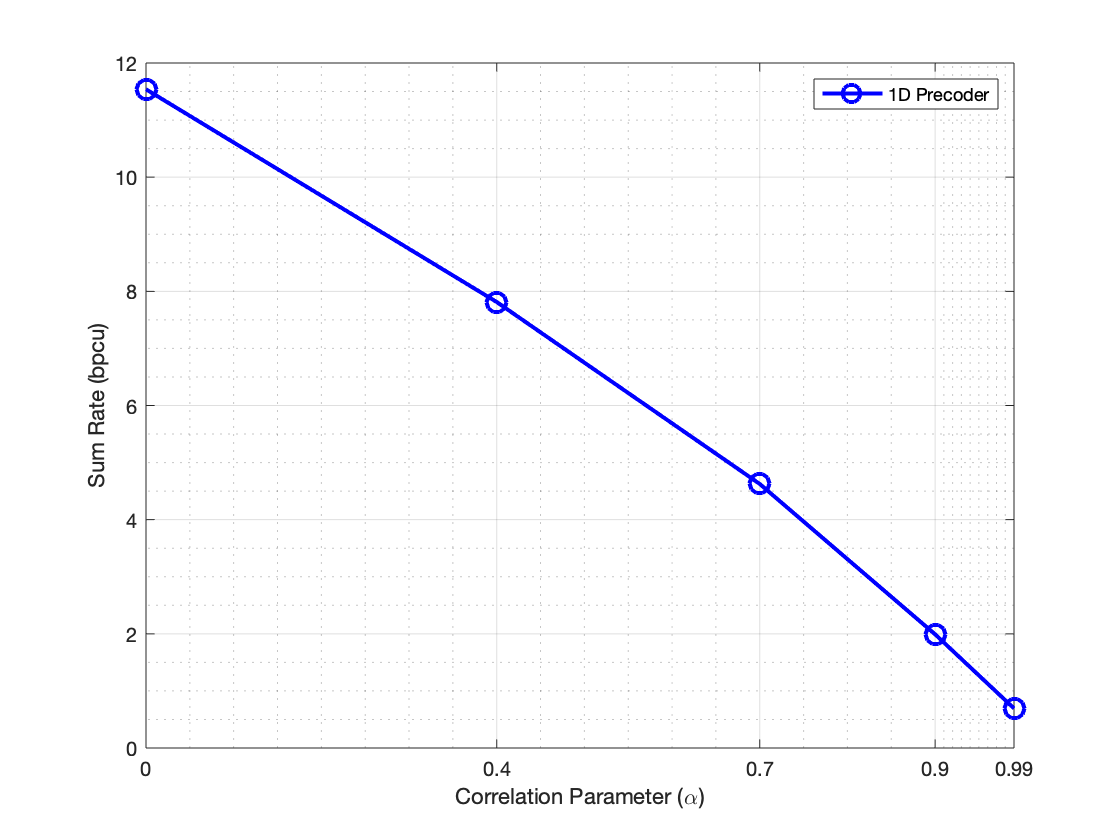

name_a = '1D Precoder';
name_b = '2D Precoder';

name1 = name_a;
name2 = strcat(name_a, ', \eta=', num2str(fix_eta));
name3 = strcat(name_a, ', \mu=', num2str(fix_mu));
name4 = name_b;
name5 = strcat(name_b, ', \eta=', num2str(fix_eta));
name6 = strcat(name_b, ', \mu=', num2str(fix_mu));

x_label_1 = 'Correlation Parameter (\alpha)';
x_label_2 = 'Correlation Parameter (\mu)';
x_label_3 = 'Correlation Parameter (\eta)';
y_label = 'Sum Rate (bpcu)';

style_1 = '-bo';
style_2 = '-ro';

figure;
plot(alpha, R1, style_1, 'DisplayName', name1, 'MarkerSize', 10);

xlabel(x_label_1, 'fontsize', 10);
ylabel(y_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(alpha);
xlim([alpha(1), alpha(sample)]);
legend();
grid on;
grid minor;

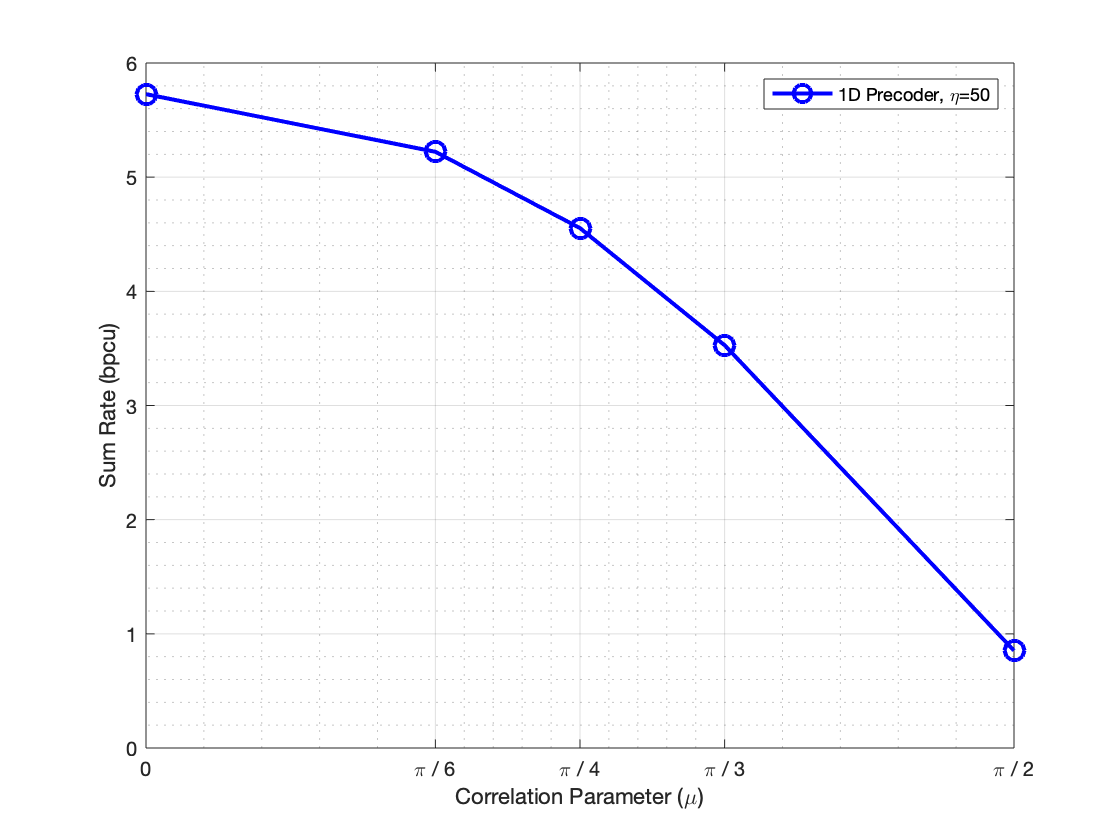



figure;
plot(mu, R2, style_1, 'DisplayName', name2, 'MarkerSize', 10);

xlabel(x_label_2, 'fontsize', 10);
ylabel(y_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(mu);
xticklabels({'0', '\pi / 6', '\pi / 4', '\pi / 3', '\pi / 2'})
xlim([mu(1), mu(sample)]);
legend();
grid on;
grid minor;

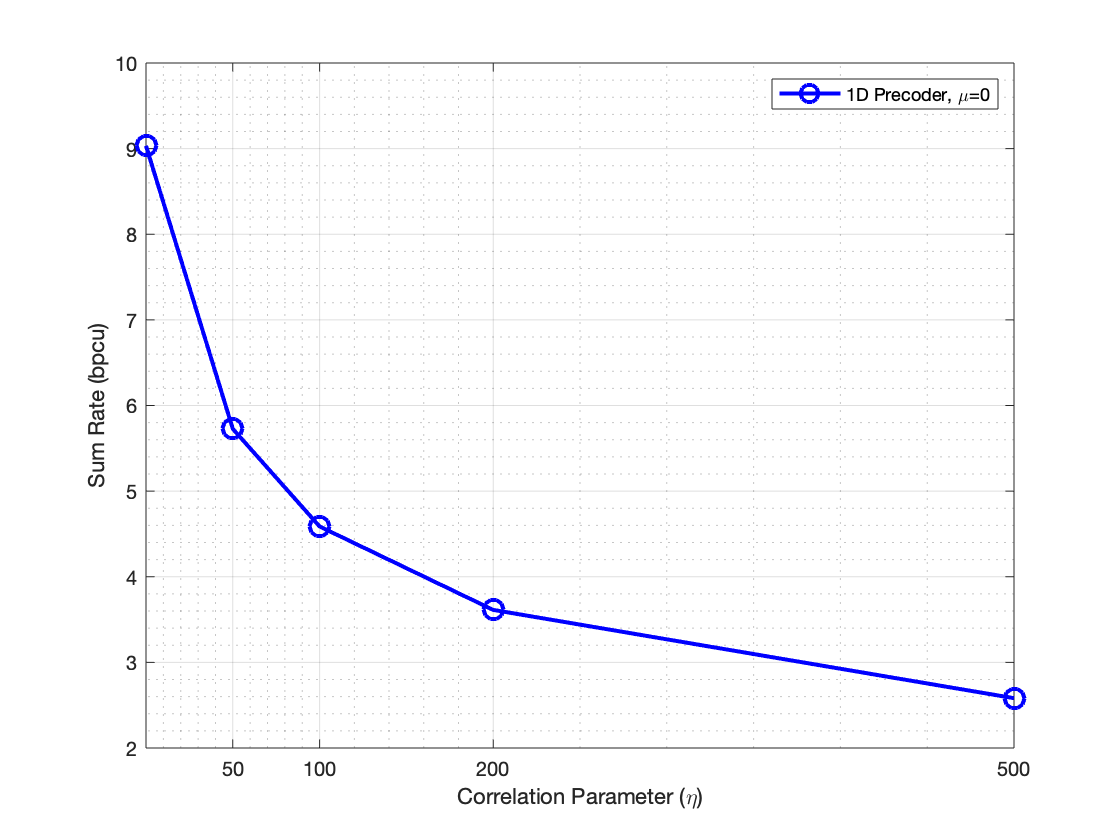



figure;
plot(eta, R3, style_1, 'DisplayName', name3, 'MarkerSize', 10);

xlabel(x_label_3, 'fontsize', 10);
ylabel(y_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(eta(2 : sample));
xlim([eta(1), eta(sample)]);
legend();
grid on;
grid minor;

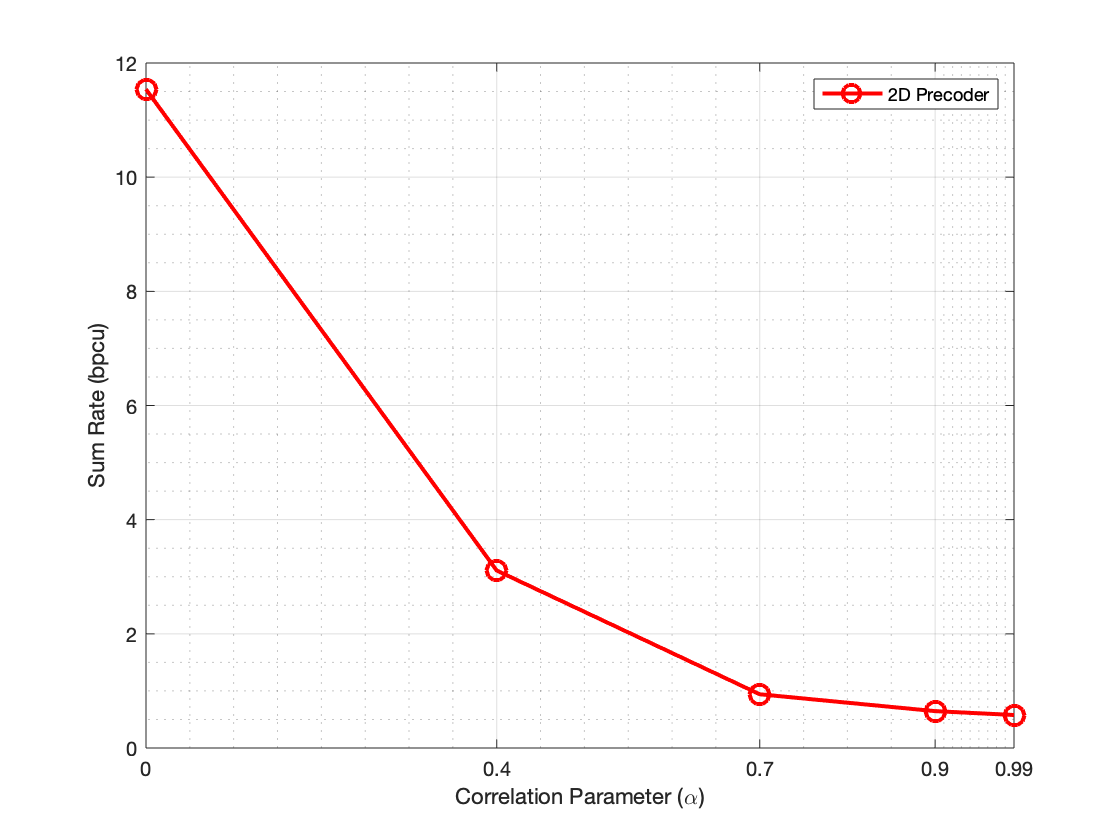


figure;
plot(alpha, R4, style_2, 'DisplayName', name4, 'MarkerSize', 10);

xlabel(x_label_1, 'fontsize', 10);
ylabel(y_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(alpha);
xlim([alpha(1), alpha(sample)]);
legend();
grid on;
grid minor;

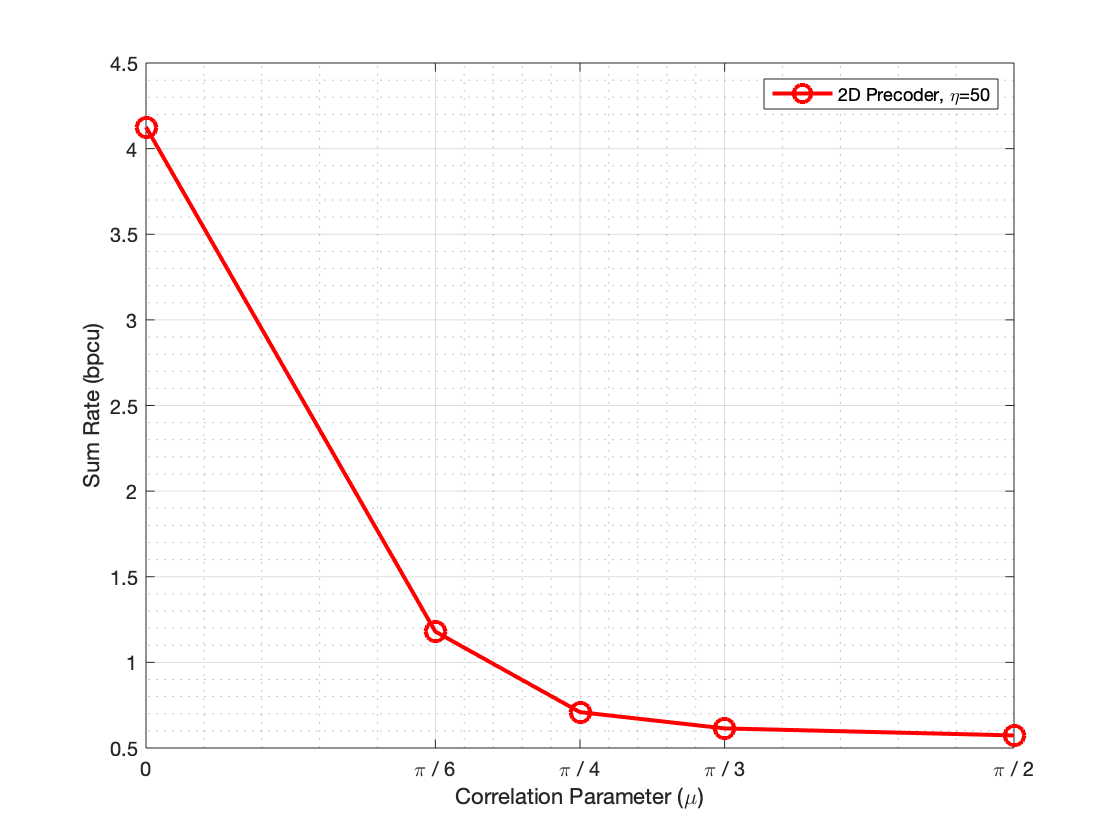



figure;
plot(mu, R5, style_2, 'DisplayName', name5, 'MarkerSize', 10);

xlabel(x_label_2, 'fontsize', 10);
ylabel(y_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(mu);
xticklabels({'0', '\pi / 6', '\pi / 4', '\pi / 3', '\pi / 2'})
xlim([mu(1), mu(sample)]);
legend();
grid on;
grid minor;

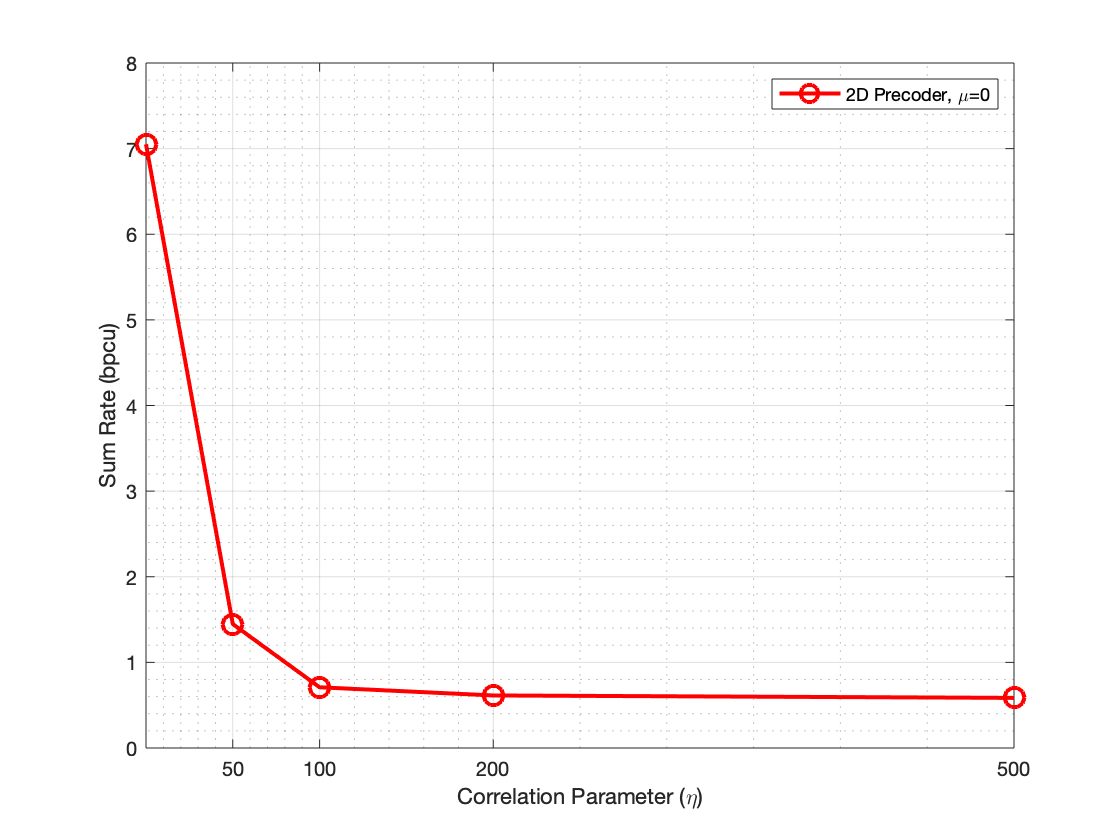



figure;
plot(eta, R6, style_2, 'DisplayName', name6, 'MarkerSize', 10);

xlabel(x_label_3, 'fontsize', 10);
ylabel(y_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(eta(2 : sample));
xlim([eta(1), eta(sample)]);
legend();
grid on;
grid minor;